# Disturbance Estimation

clear
close all

Define system matrices

A = [1/2 -1/4; 1/4 1/2];
C = eye(2);

## Estimator design

Augmented system: $\left[\matrix{ 
\hat{x}(k\!+\!1) \cr \hat{d}(k\!+\!1)}\right] =
\left[\matrix{ 
A & I  \cr 0 & I }\right] \left[\matrix{ 
\hat{x}(k) \cr \hat{d}(k)}\right] + \left[\matrix{ 
B \cr 0}\right] u(k) + \left[\matrix{L_x \cr L_d}\right]\left[C \ 0\right]\left(\left[\matrix{ 
\hat{x}(k) \cr \hat{d}(k)}\right] - \left[\matrix{ 
x(k) \cr d(k)}\right]\right)$

Aaug = [A, eye(2); zeros(2), eye(2)]; 
Caug = [eye(2), zeros(2)];

Design estimator by pole placement (duality to controller design with $A^T + C^T L^T$)

L = -(place(Aaug',Caug',[0,0,0.5,0.5]))';
eig(Aaug + L*Caug)

ans =          0
    0.5000
         0
    0.5000


## Simulation

Nsim = 10; % simulation time steps

Specify initial conditions

x(:,1) = [1;1];
d = [0.1; -0.2];
x_est(:,1) = [1;1];

d_est(:,1) = [0;0];
% d_est(:,1) = d;

Simulate autonomous system

x_aux = [x_est(:,1); d_est(:,1)];
for i = 1:Nsim-1
    x(:,i+1) = A*x(:,i) + d;
    x_aux = Aaug*x_aux + L*(Caug*x_aux - x(:,i));
    x_est(:,i+1) = x_aux(1:2); 
    d_est(:,i+1) = x_aux(3:4);
end

Plot result

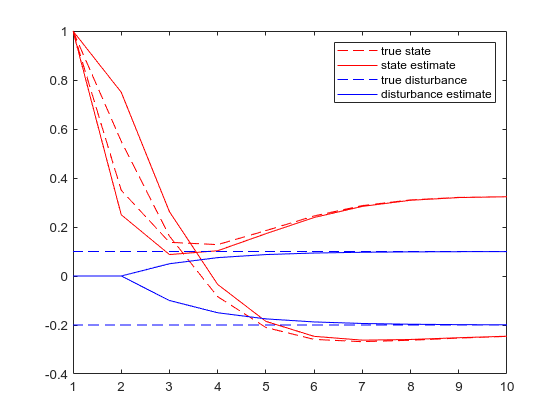

figure(1)
hold off
p1 = plot(x','r--');
hold on
p2 = plot(x_est','r');
p3 = plot([1, Nsim],[d'; d'],'b--');
p4 = plot(d_est','b');
legend([p1(1),p2(1),p3(1),p4(1)],'true state','state estimate','true disturbance','disturbance estimate');

## Alternative design

In the previous solution the estimate at time step k+1 makes use of the measured state at k. If you want the estimator to make use of the measured state k+1 you can do this by adjusting the C matrix


$$y(k) = x(k\!+\!1) = \underset{C}{\underbrace{A}} x(k) + d$$


Caug_alt = [A, eye(2)];
L_alt = -(place(Aaug',Caug_alt',[0,0,0.5,0.5]))';

## Alternative Simulation

x_alt(:,1) = [1;1];
x_est_alt(:,1) = [1;1];
d = [0.1; -0.2];

d_est_alt(:,1) = [0;0];
% d_est_alt(:,1) = d;


x_aux = [x_est_alt(:,1); d_est_alt(:,1)];
for i = 1:Nsim-1
    x_alt(:,i+1) = A*x_alt(:,i) + d;
    x_aux = Aaug*x_aux + L_alt*(Caug_alt*x_aux - x(:,i+1));   %using measurement x(k+1)
    x_est_alt(:,i+1) = x_aux(1:2); d_est_alt(:,i+1) = x_aux(3:4);
end

Plot results (estimated state is now equal to the measured state when the state is correctly initialized)

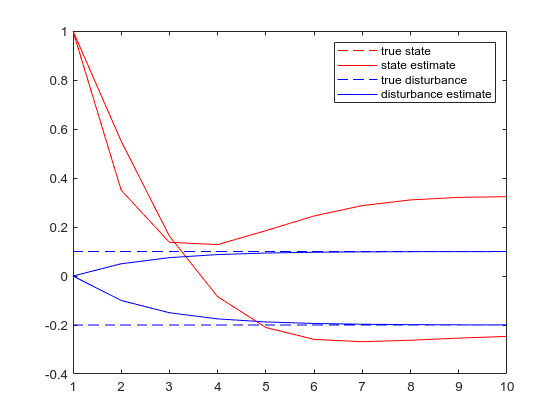

figure(2)
hold off
p1 = plot(x_alt','r--');
hold on
p2 = plot(x_est_alt','r');
p3 = plot([1, Nsim],[d'; d'],'b--');
p4 = plot(d_est_alt','b');
legend([p1(1),p2(1),p3(1),p4(1)],'true state','state estimate','true disturbance','disturbance estimate');